# **Άσκηση 2**

Σκοπός της δεύτερης άσκησης είναι ο υπολογισμός της ενέργειας των παραθύρων στα οποία αναλύεται ένα ηχητικό αρχείο και η εύρεση του παραθύρου με τη μεγαλύτερη ενέργεια.

Αρχικά, εισάγουμε το αρχείο ήχου:

clear;
clc;
[x,Fs] = audioread("guit1.wav");

Έπειτα, το αναλύουμε σε παράθυρα:

X = frame_wind(x,256,0.5);

Βρίσκουμε τον FFT του πίνακα Χ :

%Compute FFT matrix
fft_mat = fft(X);

Υπολογίζουμε την ενέργεια κάθε παραθύρου:

abs_fft_mat = abs(fft_mat);
squared_abs_fft_mat = abs_fft_mat.^2;
dim = size(squared_abs_fft_mat);
E = sum(squared_abs_fft_mat);

Στη συνέχεια, απεικονίζουμε σε ένα γράφημα την ενέργεια των παραθύρων:

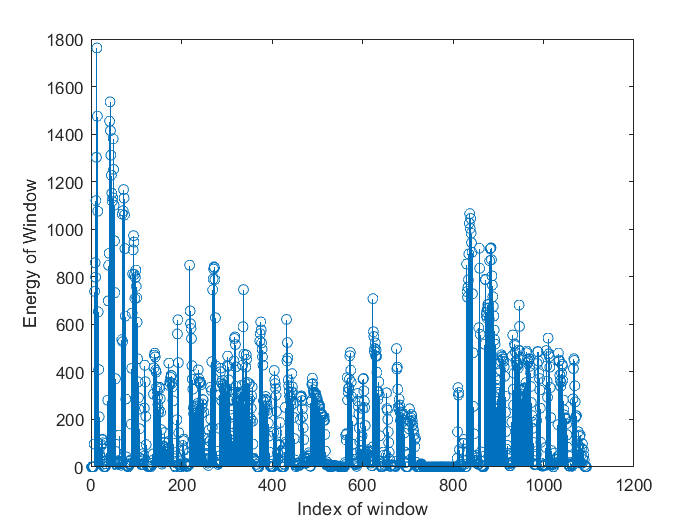

stem(E);
xlabel('Index of window');
ylabel('Energy of Window');

Τέλος, βρίσκουμε τη μέγιστη ενέργεια των παραθύρων:

%Find maximum energy of all windows
max_energy = max(E);
result = ['Η μέγιστη ενέργεια είναι: ',num2str(max_energy)];
disp(result);

Η μέγιστη ενέργεια είναι: 1762.3224
